# EEE3548 Exercise #1 DFT, 2D Convolution using FFT

## [23.03.31] [ImHyeonJeong]

#### Q1. Map the real part of $e^{j2\pi(f_xx+f_yy)}$ over the range of -50 to 50 for both x and y. Try using $f_x = f_y = 0.02$.   

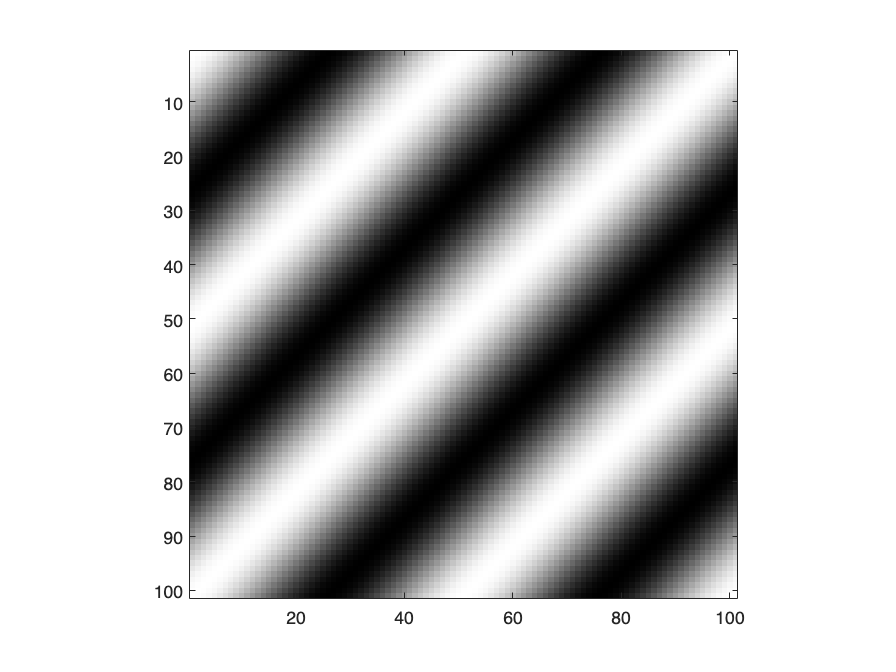

x = -50:50;
y = -50:50;
[X,Y] = meshgrid(x,y); % 2D matrix
fx = 0.02;
fy = 0.02;

img = exp(1j*2*pi*(fx*X+fy*Y));

figure; imagesc(real(img)); colormap gray; axis image;

#### Q2. Test with different spatial frequency pairs. How would you flip / rotate the direction of the 2D sinusoid?

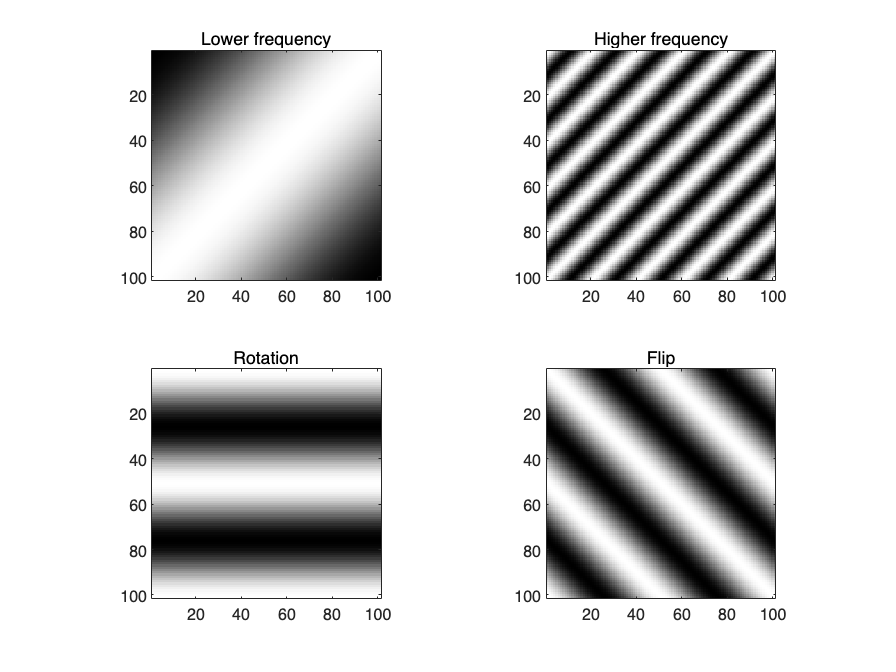

x = -50:50;
y = -50:50;
[X,Y] = meshgrid(x,y);

fx = 0.02; fy = 0.02; % original frequency
fx_l = 0.005; fy_l = 0.005; % lower frequency
fx_h = 0.05; fy_h = 0.05; % higher frequency
angle = pi/2; % angle for rotation

img_l = exp(1j*2*pi*(fx_l*X+fy_l*Y)); % lower frequency -> less sinusoid
img_h = exp(1j*2*pi*(fx_h*X+fy_h*Y)); % higher frequency -> more sinusoid
img_r = exp(1j*2*pi*(fx*X*cos(angle)+fy*Y*sin(angle))); % rotation
img_f = exp(1j*2*pi*(fx*X-fy*Y)); % flip

figure;
subplot(221); imagesc(real(img_l)); colormap gray; axis image; title('Lower frequency');
subplot(222); imagesc(real(img_h)); colormap gray; axis image; title('Higher frequency');
subplot(223); imagesc(real(img_r)); colormap gray; axis image; title('Rotation');
subplot(224); imagesc(real(img_f)); colormap gray; axis image; title('Flip');

#### Q3. Defind a function that performs 1D DFT in matrix-vector mutiplication for a given 1D input. (at the end of the file)

ifimg = rand(10,1);
G_dft = DFT(ifimg);
G_fft = fft(ifimg);

img_in = ['Input: ' mat2str(ifimg', 5)];
dft_out = ['DFT Output: ' mat2str(G_dft', 5)];
fft_out = ['FFT Output: ' mat2str(G_fft', 5)];

fprintf('%s\n%s\n%s', img_in, dft_out, fft_out);

Input: [0.087699 0.24113 0.10429 0.23667 0.5336 0.13936 0.3254 0.83861 0.39323 0.21459]
DFT Output: [3.1146 -0.55646-0.7093i -0.63908+0.011206i 0.54037+0.74689i -0.35055-0.40446i -0.22614+2.4595e-16i -0.35055+0.40446i 0.54037-0.74689i -0.63908-0.011206i -0.55646+0.7093i]
FFT Output: [3.1146 -0.55646-0.7093i -0.63908+0.011206i 0.54037+0.74689i -0.35055-0.40446i -0.22614 -0.35055+0.40446i 0.54037-0.74689i -0.63908-0.011206i -0.55646+0.7093i]

#### Q4. Compare the speed with the built-in fft function. Try different input sizes.

x = rand(256);

X_DFT = DFT(x);
dft_time = toc;

tic
X_fft = fft(x);
fft_time = toc;

dft_time = ['DFT Elasped time: ' num2str(dft_time, '%.5f'), 's'];
fft_time = ['FFT Elasped time: ' num2str(fft_time, '%.5f'), 's'];

fprintf('%s\n%s\n', dft_time, fft_time)

DFT Elasped time: 1.05420s
FFT Elasped time: 0.00148s


#### Q5. Perform 2D FFT using fft2() and plot the magnitude spectrum. 

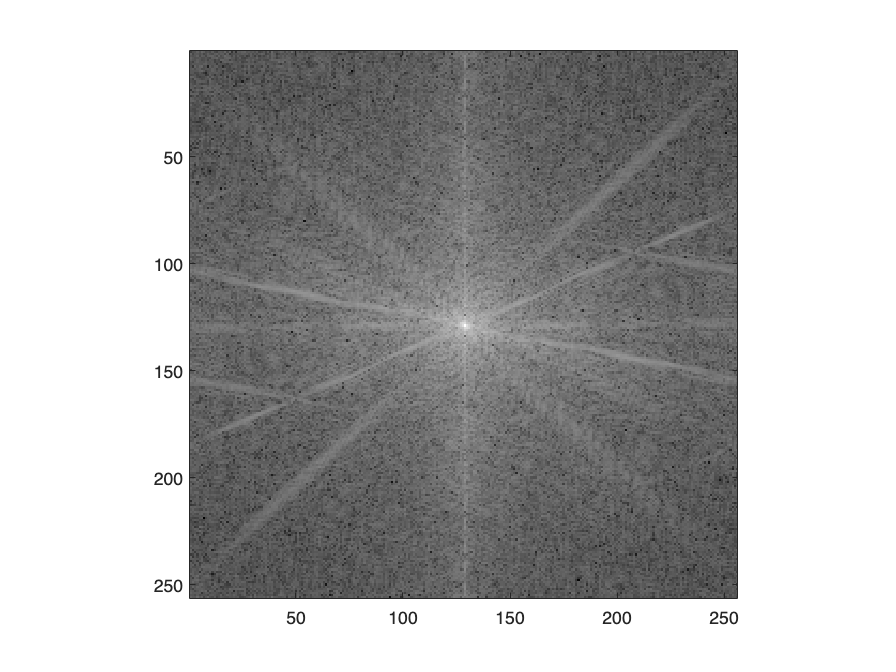

img = imread('cameraman.tif');
fimg = fftshift(fft2(img));

figure; imagesc(log(abs(fimg))); colormap gray; axis image;

#### Q6. Define 2D sinusoidal images as in Q1 in the spatial frequency domain. Take IFT and take abs to visualize it. How can you define the spatial frequencies/directions of the sinusoidal pattern? How would you shift the phase of the sinusoid?

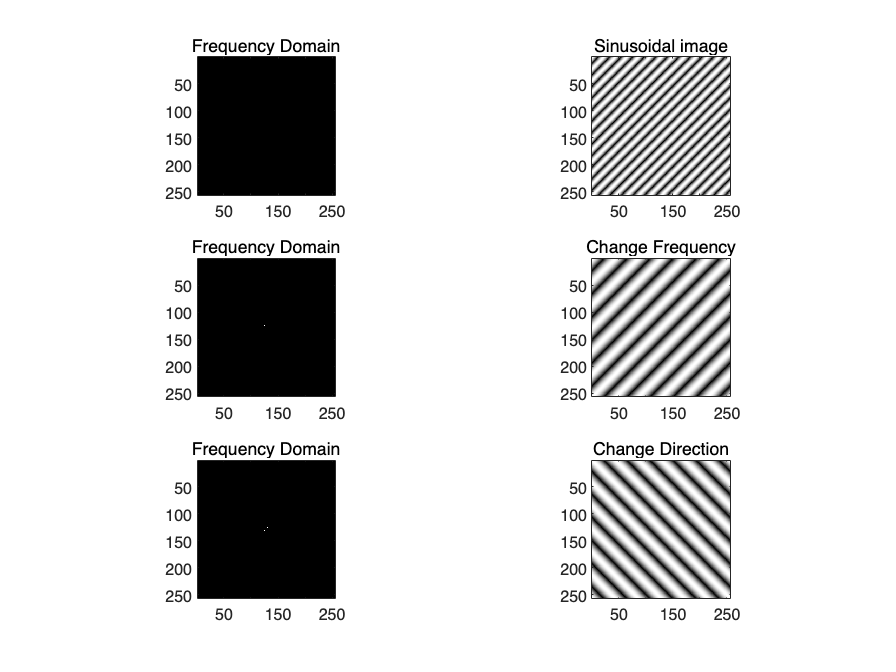

fx = 6; fy = 6;
spatial_img = zeros(256);
spatial_img(128-fx, 128-fy) = 1;
spatial_img(128+fx, 128+fy) = 1;
subplot(321); imagesc(spatial_img); colormap gray; axis image; title('Frequency Domain')

sinusoidal = ifft2(spatial_img);
spectrum = abs(fftshift(sinusoidal));
subplot(322); imagesc(spectrum); colormap gray; axis image; title('Sinusoidal image')

fx = 3; fy = 3;
spatial_img = zeros(256);
% 좀 더 원점에 가깝게 주파수 도메인의 픽셀에 점 찍음
spatial_img(128-fx, 128-fy) = 1;
spatial_img(128+fx, 128+fy) = 1;
subplot(323); imagesc(spatial_img); colormap gray; axis image; title('Frequency Domain')

sinusoidal = ifft2(spatial_img);
spectrum = abs(fftshift(sinusoidal));
subplot(324); imagesc(spectrum); colormap gray; axis image; title('Change Frequency')

fx = 3; fy = -3;
spatial_img = zeros(256);
spatial_img(128-fx, 128-fy) = 1;
spatial_img(128+fx, 128+fy) = 1;
subplot(325); imagesc(spatial_img); colormap gray; axis image; title('Frequency Domain')

sinusoidal = ifft2(spatial_img);
spectrum = abs(fftshift(sinusoidal));
subplot(326); imagesc(spectrum); colormap gray; axis image; title('Change Direction')

#### **Q7. Based on the lecture, perform 2D Linear convolution between the cameraman.tif and 2D gaussian function with **$\sigma$ **= 30. You can use built-in function for 2D gaussian.**

#### **(a) Check the FT of the 2D gaussian function**

#### **(b) Generate 2D Linear convolution using FFT (you may pad zeros to the edge of the images)**

#### **(c) Check the result both the frequency and spatial domain. **Discuss the Results

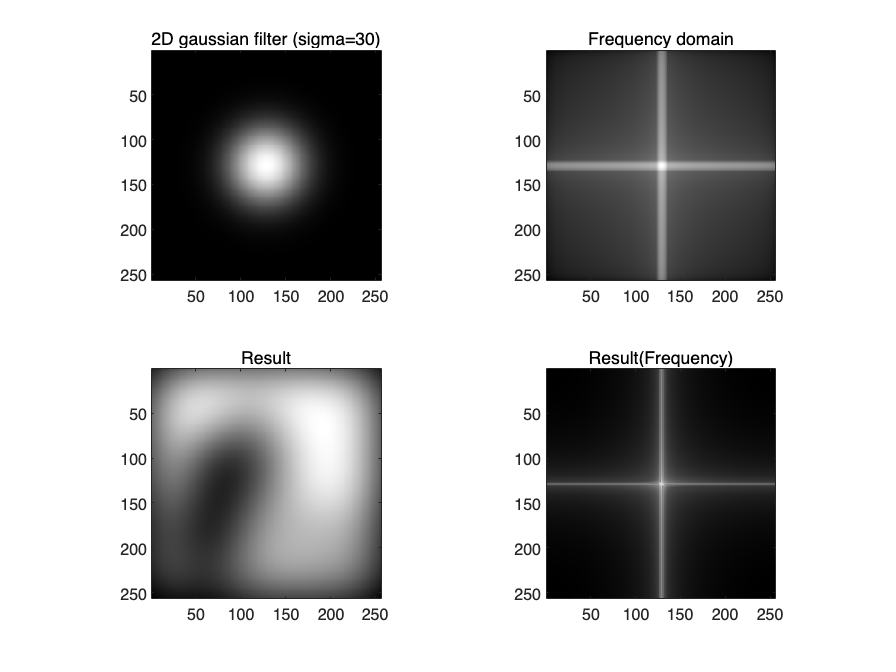

% Read (256x256) image
img = imread('cameraman.tif');

% (a) FT of the 2D gaussian function (sigma = 30)
h = fspecial('gaussian', length(img), 30);
H = fftshift(fft2(h));

% (b),(c) 2D Linear convolution using FFT
out = fft_conv(img, h); % spatial domain
Out = fftshift(fft2(out)); % frequency domain

% Plot
figure;
subplot(221); imagesc(h); colormap gray; axis image; title('2D gaussian filter (sigma=30)');
subplot(222); imagesc(log(abs(H))); colormap gray; axis image; title('Frequency domain');
subplot(223); imagesc(out); colormap gray; axis image; title('Result');
subplot(224); imagesc(log(abs(Out))); colormap gray; axis image; title('Result(Frequency)');

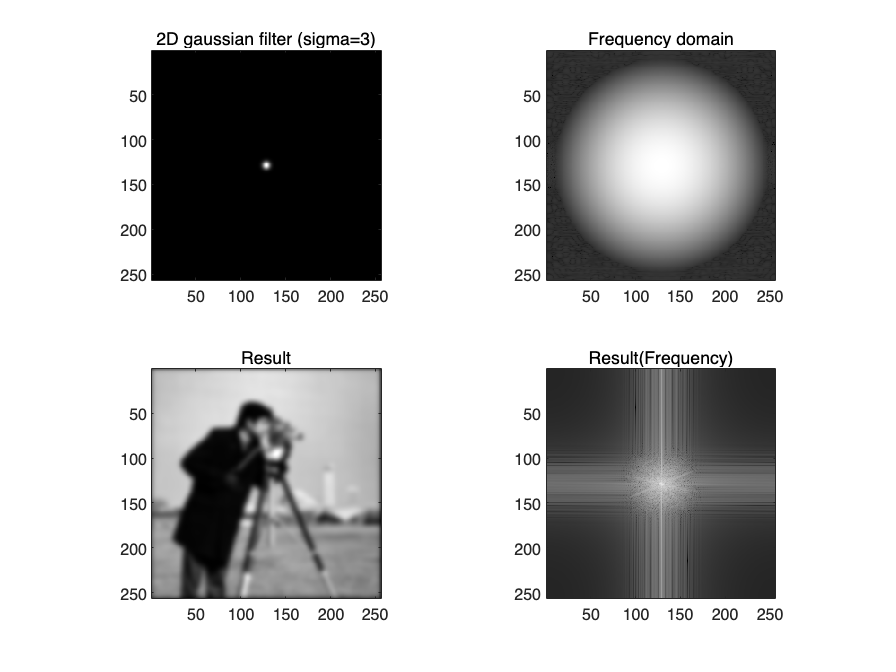

% (a) FT of the 2D gaussian function (sigma = 3)
h = fspecial('gaussian', length(img), 3);
H = fftshift(fft2(h));

% (b),(c) 2D Linear convolution using FFT
out = fft_conv(img, h); % spatial domain
Out = fftshift(fft2(out)); % frequency domain

% Plot
figure;
subplot(221); imagesc(h); colormap gray; axis image; title('2D gaussian filter (sigma=3)');
subplot(222); imagesc(log(abs(H))); colormap gray; axis image; title('Frequency domain');
subplot(223); imagesc(out); colormap gray; axis image; title('Result');
subplot(224); imagesc(log(abs(Out))); colormap gray; axis image; title('Result(Frequency)');

### Discussion

Gaussian filter는 Gaussian probability distribution function에 기반한 Low pass filter로, 이미지에 blurring 효과를 적용할 수 있다. 이는 filter를 plot 했을 때, 중앙 부분(저주파 성분)이 흰색, 바깥 부분(고주파 성분)이 검은색을 띄는 것을 통해 저주파 성분들을 통과시키고 고주파 성분들은 차단하는 Low pass filter임을 확인할 수 있었다. 또한, Gaussian filter는 sigma (standaard deviation)와 kernel size를 조절할 수 있다. convolution은 이론적으로는 무한대의 영역에서 수행되지만, digital filtering에서는 무한한 크기의 window를 생성하는 것이 불가능하기에 적당히 영역을 제한하여 filtering을 수행해야 한다. 이 때, sigma값을 조절함으로써 window size를 결정할 수 있다. 위 결과에서 sigma=3에 비해 sigma=30의 2D gaussian filter의 흰색 크기가 더 큰 것을 확인할 수 있었다. frequency domain 결과를 통해서도 sigma=30일 때 저주파 성분에 좀 더 집중적으로 filtering이 적용될 것임을 예상할 수 있었다. sigma값이 클수록 Gaussian function의 curve가 평평한 형태를 띄게 되고, blurring 효과가 더 커진다. 이는 위 결과에서도 확인할 수 있었는데, sigma=3의 결과에 비해 sigma=30의 결과에서 Result image에 더 많은 blurring이 적용된 것을 볼 수 있다. image를 frequency domain에서 plot 했을 때 나타나는 일부 밝은 흰색 부분은 noise가 존재하는 위치로 예상할 수 있는데, Gaussian filter를 이용함으로써 image에 존재하는 고주파 성분을 줄여 noise를 제거할 수 있다. 

## Function

function G = DFT(g)
    N = length(g);
    n = 0:N-1;
    k = reshape(n, [N,1]);
    e = exp(-2j * pi * k * n / N);
    G = transpose(e * transpose(g));
end

function out = fft_conv(img, filter)
    % Zero padding for preventing aliasing
    img_pad = padarray(img, [length(img)/2 length(img)/2], 0, 'both');
    filter_pad = padarray(filter, [length(img)/2 length(img)/2], 0, 'both');

    % Convolution by fft
    out = ifftshift(ifft2(ff2(img_pad).*ff2(filter_pad)));

    % remove padding
    target_size = [length(img) length(img)];
    window = centerCropWindow2d(size(out), target_size);
    out = imcrop(out, window);
end

% function G = DFT(g)
%     M = length(g);
%     W = zeros(M,M);
%     for a = 1:M
%         for b = 1:M
%             W(a,b) = exp(-1j*2*pi/M*(a-1)*(b-1));
%         end
%     end
%     G = W * g;
% end

% function out = fft_conv(img, filter)
%     % Sizes
%     img_size = size(img);
%     filter_size = size(filter);
% 
%     % Zero padding for preventing aliasing
%     max_size = max(img_size, filter_size);
%     min_size = min(img_size, filter_size);
%     S = floor(min_size.*0.5);
%     Size = max_size + S; % enough size for convolution
%     img = padarray(img, Size-img_size, 'post');
%     filter = padarray(filter, Size-filter_size, 'post');
% 
%     % Convolution by fft
%     out = ifft2(fft2(img).*fft2(filter));
% 
%     % remove padding
%     out = out(1+S(1):end,1+S(2):end);
% end